# FF_DS_AZ_CTS_LOOP Dynamic Savings Loop Continuous Distribution

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**ff_ds_az_cts_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_ds_az_cts_loop.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **F(a,z) discrete probability mass function given policy function solution with continuous savings choices.

- Distribution for Common Choice and States Grid ***Loop***: ff_ds_az_cts_loop

- Distribution for States Grid + Continuous Exact Savings as Share of Cash-on-Hand ***Loop***: [**ff_ds_az_cts_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_ds_az_cts_loop.m)

## Test FF_DS_AZ_CTS_LOOP Defaults

Call the function with defaults. By default, shows the asset policy function summary. Model parameters can be changed by the mp_params.

Elapsed time is 1.029654 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
          i    idx    ndim    numel    rowN    colN     sum       mean      std      coefvari    min     max  
          _    ___    ____    _____    ____    ____    ______    ______    ______    ________    ___    ______

    ap    1     1      2       700     100      7      9863.4    14.091    14.388     1.0211      0     50.117

xxx TABLE:ap xxxxxxxxxxxxxxxxxx
    

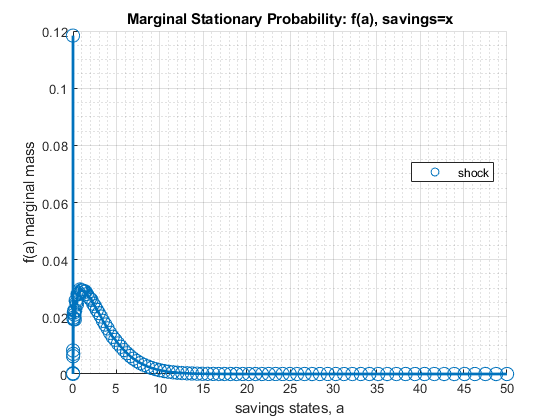

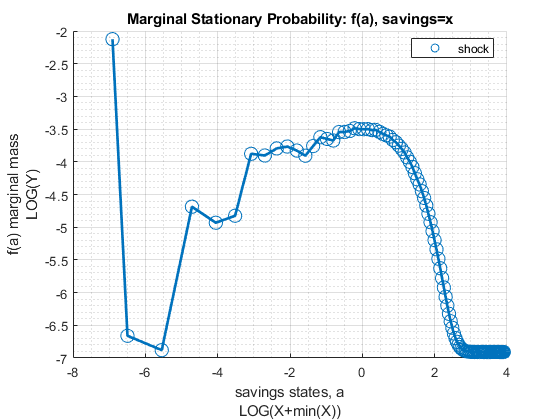

xxx tb_outcomes: all stats xxx
    OriginalVariableNames         ap            v             c             y            coh        savefraccoh
    ______________________    __________    __________    __________    __________    __________    ___________

    {'mean'              }        1.6576        5.0855        1.4665        1.4663        3.1241       0.37319 
    {'sd'                }        1.9603        1.7128         0.362       0.51116        2.2726       0.24899 
    {'coefofvar'         }        1.1826       0.33679       0.24684        0.3486       0.72744       0.66717 
    {'min'               }             0       0.87463       0.58543       0.58543       0.58543             0 
    {'max'               }        50.117        16.344    

%mp_params
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('fl_crra') = 1.5;
mp_params('fl_beta') = 0.94;
% call function
ff_ds_az_cts_loop(mp_params);

## Test FF_DS_AZ_CTS_LOOP Speed Tests

Call the function with different a and z grid size, print out speed:

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};
mp_support('ls_ddcmd') = {};
mp_support('ls_ddgrh') = {};
mp_support('bl_show_stats_table') = false;
% A grid 50, shock grid 5:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
ff_ds_az_cts_loop(mp_params, mp_support);

Elapsed time is 0.610510 seconds.
FF_DS_AZ_CTS_LOOP finished. Distribution took = 0.081975


% A grid 100, shock grid 7:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 7;
ff_ds_az_cts_loop(mp_params, mp_support);

Elapsed time is 1.114978 seconds.
FF_DS_AZ_CTS_LOOP finished. Distribution took = 0.18449


% A grid 200, shock grid 9:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 200;
mp_params('it_z_n') = 9;
ff_ds_az_cts_loop(mp_params, mp_support);

Elapsed time is 2.014970 seconds.
FF_DS_AZ_CTS_LOOP finished. Distribution took = 0.62806


## Test FF_DS_AZ_CTS_LOOP A grid 100 Shock grid 7

Call the function with different a and z grid size, print out speed:

Elapsed time is 0.953345 seconds.
FF_DS_AZ_CTS_LOOP finished. Distribution took = 0.23426


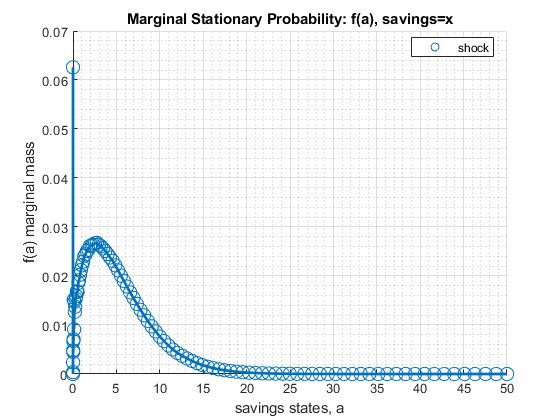

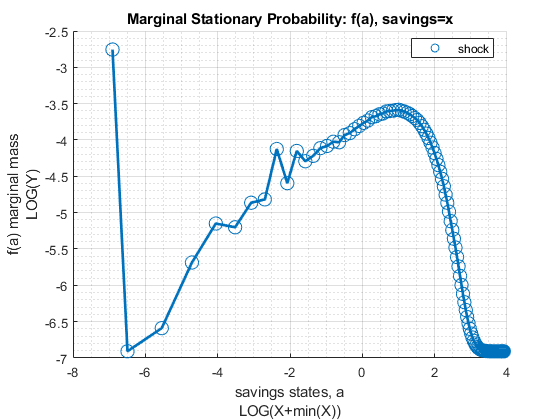

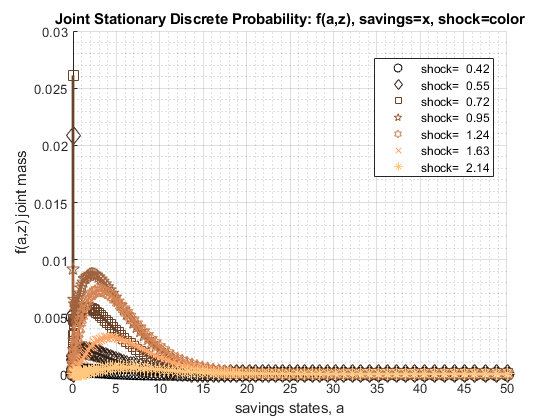

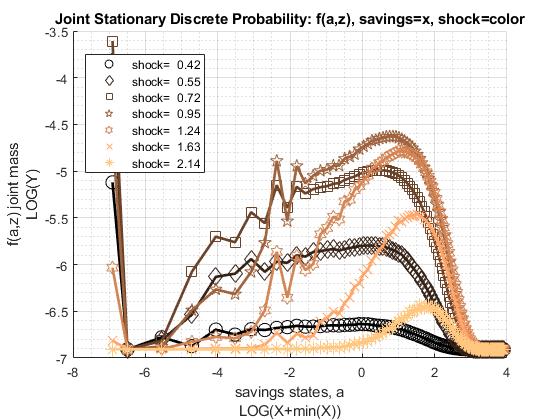

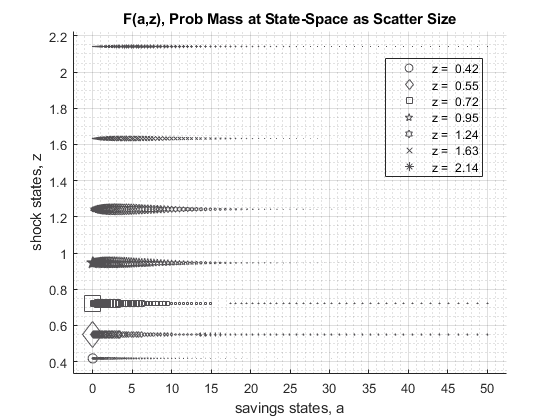

xxx tb_outcomes: all stats xxx
    OriginalVariableNames         ap            v             c             y            coh        savefraccoh
    ______________________    __________    __________    __________    __________    __________    ___________

    {'mean'              }        3.2216        6.9329        1.5295        1.5289        4.7511       0.52357 
    {'sd'                }        3.2562        2.1508       0.34914        0.5307        3.5687       0.25504 
    {'coefofvar'         }        1.0107       0.31024       0.22827       0.34711       0.75113       0.48712 
    {'min'               }             0        1.7008       0.58543       0.58543       0.58543             0 
    {'max'               }        50.789        19.213    

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};
mp_support('ls_ddcmd') = {};
mp_support('ls_ddgrh') = {'faz','fa'};
mp_support('bl_show_stats_table') = true;
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 7;
ff_ds_az_cts_loop(mp_params, mp_support);

## Test FF_DS_AZ_CTS_LOOP A grid 300 Shock grid 25

Elapsed time is 11.056197 seconds.
FF_DS_AZ_CTS_LOOP finished. Distribution took = 2.3435


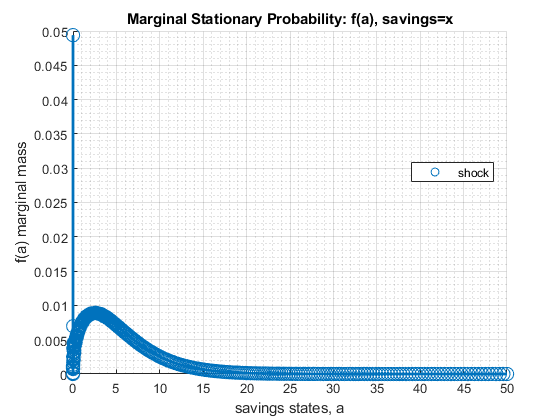

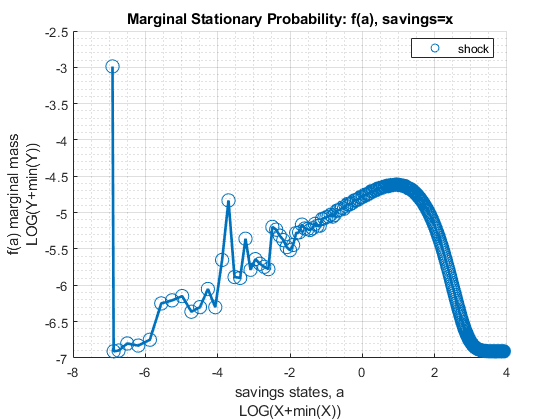

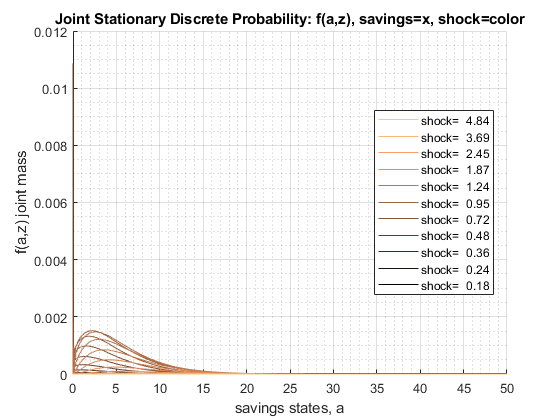

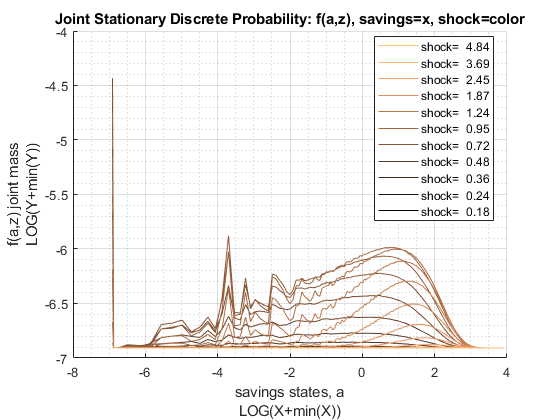

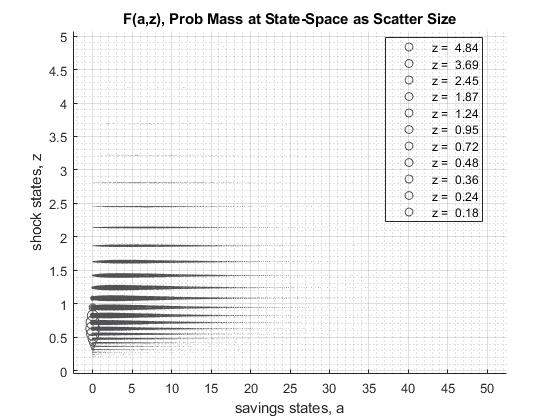

xxx tb_outcomes: all stats xxx
    OriginalVariableNames         ap            v             c             y            coh        savefraccoh
    ______________________    __________    __________    __________    __________    __________    ___________

    {'mean'              }        3.2612        6.9497        1.5318        1.5305         4.793       0.52715 
    {'sd'                }        3.3352        2.1663       0.35078        0.5359        3.6495       0.25199 
    {'coefofvar'         }        1.0227       0.31171         0.229       0.35014       0.76143       0.47803 
    {'min'               }             0       -2.7616       0.25871       0.25871       0.25871             0 
    {'max'               }        54.451        20.418    

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};
mp_support('ls_ddcmd') = {};
mp_support('ls_ddgrh') = {'faz','fa'};
mp_support('bl_show_stats_table') = true;
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 300;
mp_params('it_z_n') = 25;
ff_ds_az_cts_loop(mp_params, mp_support);

## Test FF_DS_AZ_CTS_LOOP A grid 300 Shock grid 50

Elapsed time is 20.983438 seconds.
FF_DS_AZ_CTS_LOOP finished. Distribution took = 5.2169


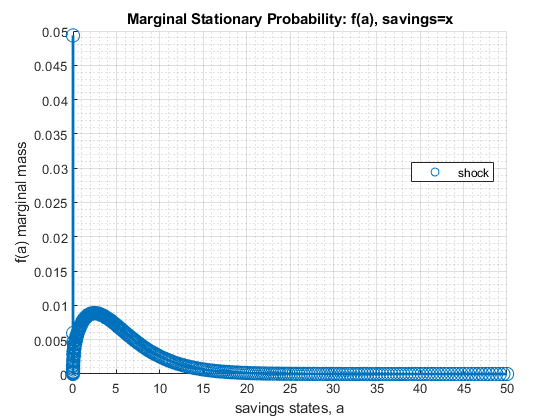

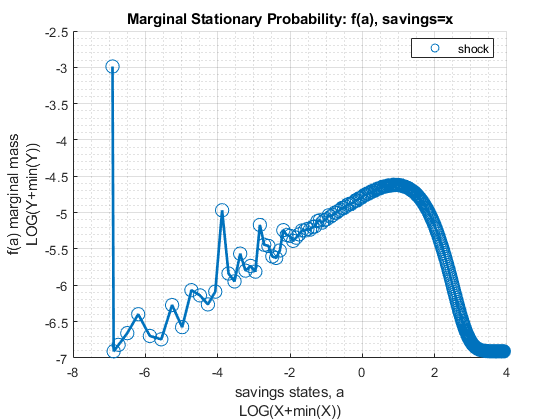

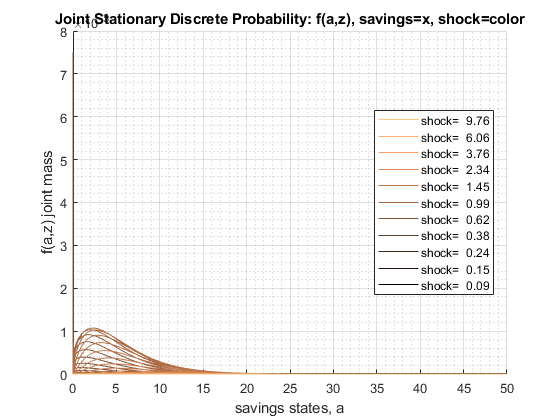

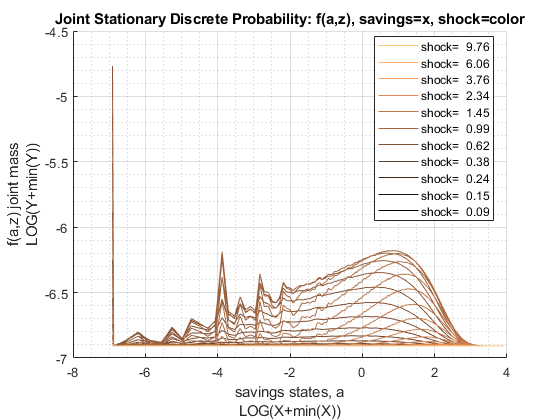

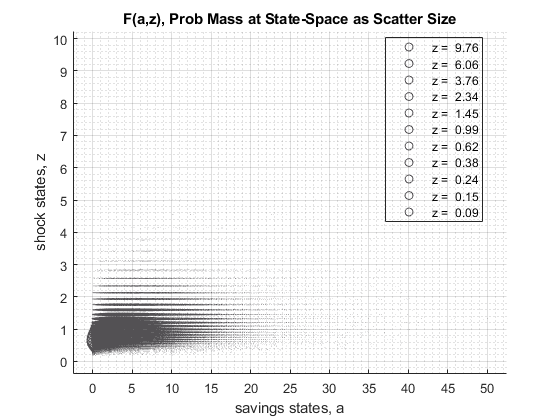

xxx tb_outcomes: all stats xxx
    OriginalVariableNames         ap             v             c             y            coh        savefraccoh
    ______________________    __________    ___________    __________    __________    __________    ___________

    {'mean'              }        3.2794          6.957        1.5328        1.5312        4.8122       0.52801 
    {'sd'                }        3.3623         2.1722       0.35142       0.53693        3.6772       0.25195 
    {'coefofvar'         }        1.0253        0.31224       0.22927       0.35065       0.76415       0.47717 
    {'min'               }             0        -7.6866       0.12843       0.12843       0.12843             0 
    {'max'               }        61.275         22.

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};
mp_support('ls_ddcmd') = {};
mp_support('ls_ddgrh') = {'faz','fa'};
mp_support('bl_show_stats_table') = true;
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 300;
mp_params('it_z_n') = 50;
ff_ds_az_cts_loop(mp_params, mp_support);